clc
clear

% 初始种群数量
% 初始种群数量可能需要调整以反映参数的变化
N0 = 200; % 可能需要增加初始N
C0 = 120;  % 调整C
Pre0 = 50; % 减少Pre
Par0 = 45; % 略微调整Par
AP0 = 400; % 减少AP
y0 = [N0; C0; Pre0; Par0; AP0]; % 设置初始条件
tspan = [0 10]; % 设置时间范围

figure; % 创建一个新图形窗口

Fs = [2, 4, 6, 8]; % 环境因素F的不同值

for i = 1:length(Fs)
    F = Fs(i); % 当前的环境因素值
    % 定义一个匿名函数，将当前F值传递给mySystem
    mySystemWithF = @(t, y) mySystem(t, y, F);
    % 调用ode45求解器
    [t, y] = ode45(mySystemWithF, tspan, y0);
    % 绘图
    subplot(2, 2, i); % 2x2的子图中的第i个
    plot(t, y(:,1)+50, '-r', t, y(:,2)+20, '-b', t, y(:,3)+70, '-g', t, y(:,4)+40, '-m', t, y(:,5)+50, '-c');
    legend('N(t)', 'N_C(t)', 'N_P_r_e(t)', 'N_P_a_r(t)', 'N_P_r(t)');
    xlabel('time');
    ylabel('population');
    title([ ' population when F = ','0.', num2str(F)]);
end

% 初始种群数量
N0 = 200;
C0 = 120;
Pre0 = 50;
Par0 = 45;
AP0 = 400;
y0 = [N0; C0; Pre0; Par0; AP0]; % 设置初始条件
tspan = [0 10]; % 设置时间范围

figure; % 创建一个新图形窗口

Fs = [0.46, 0.48, 0.5, 0.52 ,0.54]; % 环境因素F的不同值

% 绘制Pre的数量随时间变化的曲线
hold on; % 保持图形，以便在同一幅图上绘制多条曲线
for i = 1:length(Fs)
    F = Fs(i); % 当前的环境因素值
    % 定义一个匿名函数，将当前F值传递给mySystem
    mySystemWithF = @(t, y) mySystem(t, y, F);
    % 调用ode45求解器
    [t, y] = ode45(mySystemWithF, tspan, y0);
    % 绘图，仅绘制Pre数量的变化
    plot(t, y(:,3), 'DisplayName', sprintf('F = %.1f', F));
end
hold off; % 解除保持
legend show; % 显示图例
xlabel('Time');
ylabel('Population of Pre');
title('Population of Pre over Time for Different F Values');
figure; % 创建一个新图形窗口
hold on; % 保持图形，以便在同一幅图上绘制多条曲线

% 使用色彩渐变
colors = jet(length(Fs)); % 创建一个色彩渐变数组

for i = 1:length(Fs)
    F = Fs(i); % 当前的环境因素值
    mySystemWithF = @(t, y) mySystem(t, y, F); % 定义匿名函数
    [t, y] = ode45(mySystemWithF, tspan, y0); % 调用ode45求解器
    plot(t, y(:,3), 'DisplayName', sprintf('F = %.1f', F), 'Color', colors(i,:)); % 绘图，使用色彩渐变
end

hold off; % 解除保持
grid on; % 显示网格
legend show; % 显示图例
xlabel('Time');
ylabel('Population of Pre');
title('Sensitivity Analysis of Pre');


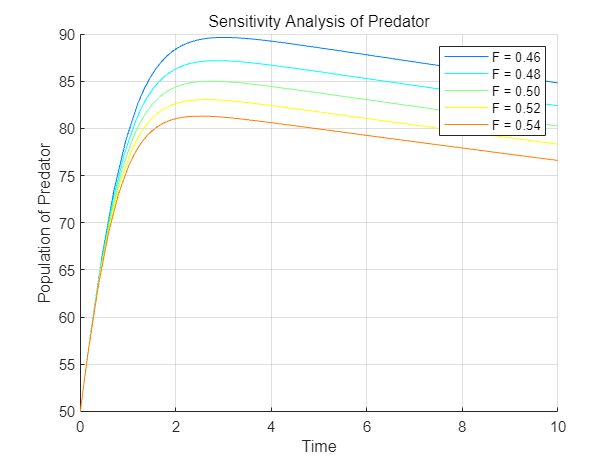

clc
clear

% 初始种群数量
N0 = 200;
C0 = 120;
Pre0 = 50;
Par0 = 45;
AP0 = 400;
y0 = [N0; C0; Pre0; Par0; AP0]; % 设置初始条件
tspan = [0 10]; % 设置时间范围

figure; % 创建一个新图形窗口
hold on; % 保持图形，以便在同一幅图上绘制多条曲线

Fs = [4.6, 4.8, 5, 5.2, 5.4]; % 环境因素F的实际值

% 使用色彩渐变
colors = jet(length(Fs)); % 创建一个色彩渐变数组

for i = 1:length(Fs)
    F = Fs(i); % 当前的环境因素值
    mySystemWithF = @(t, y) mySystem(t, y, F); % 定义匿名函数
    [t, y] = ode45(mySystemWithF, tspan, y0); % 调用ode45求解器
    plot(t, y(:,3), 'DisplayName', sprintf('F = %.2f', F / 10), 'Color', colors(i,:)); % 绘图，图例显示F值缩小10倍
end

hold off; % 解除保持
grid on; % 显示网格
legend show; % 显示
xlabel('Time');
ylabel('Population of Predator');
title('Sensitivity Analysis of Predator');


figure(1)
plot(pre_prey,pre_shark,'--r',past_prey,past_shark,'-b')
legend('战前','战后')
title('鲨鱼和食饵数量变化的相轨线图')
xlabel('食饵数量');   ylabel('鲨鱼数量')

figure(2)
plot(t1,pre_prey,'--r',t1,pre_shark,'-r',t2,past_prey,'--b',t2,past_shark,'-b')
legend('战前食饵数量','战前鲨鱼数量','战后食饵数量','战后鲨鱼数量')
xlabel('时间');   ylabel('数量')

% 鲨鱼比例  =  鲨鱼数量 /（鲨鱼数+食饵数）
pre_rate=pre_shark./(pre_prey+pre_shark);  % 战前的鲨鱼比例    
past_rate=past_shark./(past_prey+past_shark);   % 战后的鲨鱼比例
figure(3)
plot(t1,pre_rate,'--r',t2,past_rate,'-b')
legend('战前的鲨鱼比例','战后的鲨鱼比例')

F = Fs(1); % 当前的环境因素值
P = 0.78 - 0.22 * F/10;
% 定义一个匿名函数，将当前F值传递给mySystem
mySystemWithF = @(t, y) mySystem(t, y, F);
% 调用ode45求解器
[t, y] = ode45(mySystemWithF, tspan, y0);
% 绘图
figure(2)
plot(t, y(:,1)+50, '-r', t,(y(:,1)+50)*P,'-b',t,(y(:,1)+50)*(1-P),'-g');
legend('N(t)', 'M(t)', 'W(t)');
xlabel('time');
ylabel('population');
title([ ' population when F = ','0.', num2str(F),' , P_0 = 0.736']);

% 时间向量
t = linspace(5, 30, 200);

% 初始种群数量
N0 = 250; 

% 指数衰减函数的衰减系数
kM = 0.1; % 雄性数量的衰减系数
kW = 0.15; % 雌性数量的衰减系数，大于kM

% 雄性和雌性数量的计算
M = N0/2 * exp(-kM * t)-1;
W = N0/2 * exp(-kW * t)+1;

% 确保总数N = M + W
N = M + W;

% 画图
figure;
plot(t, N, 'k', 'LineWidth', 2);
hold on;
plot(t, M, 'b--', 'LineWidth', 2);
plot(t, W, 'r:', 'LineWidth', 2);
hold off;

% 添加图例和标签
legend('N(t) - Total', 'M(t) - Males', 'W(t) - Females');
xlabel('Time');
ylabel('Population');
title('Population Dynamics');
grid on;
figure(4)

plot(t, M./N, 'b', 'LineWidth', 2);
hold on;
plot(t, W./N, 'r', 'LineWidth', 2);
hold off;
% 添加图例和标签
legend('P_M(t) - M/N', 'P_W(t) - W/N');
xlabel('Time');
ylabel('Sex Ratio');
title('Sex Ratio Dynamics');

% 时间向量
t = linspace(0, 10, 200);

% 初始种群数量
N0 = 250;

% 初始雄性和雌性数量的比例，给雄性一个稍微大一些的比例
M0 = N0 * 0.6;
W0 = N0 * 0.4;

% 指数衰减函数的衰减系数，略微调整使得性别比例变化有弧度
kM = 0.12; % 雄性数量的衰减系数
kW = 0.18; % 雌性数量的衰减系数

% 雄性和雌性数量的计算
M = M0 * exp(-kM * t);
W = W0 * exp(-kW * t);

% 确保总数N = M + W
N = M + W;

% 绘制总种群数量图
figure;
plot(t, N, 'k', 'LineWidth', 2);
hold on;
plot(t, M, 'b--', 'LineWidth', 2);
plot(t, W, 'r:', 'LineWidth', 2);
hold off;

% 添加图例和标签
legend('N(t) - Total', 'M(t) - Males', 'W(t) - Females');
xlabel('Time');
ylabel('Population');
title('Population Dynamics');
grid on;

% 绘制性别比例图
figure;
plot(t, M./N, 'b', 'LineWidth', 2);
hold on;
plot(t, W./N, 'r', 'LineWidth', 2);
hold off;

% 添加图例和标签
legend('P_M(t) - M/N', 'P_W(t) - W/N');
xlabel('Time');
ylabel('Sex Ratio');
title('Sex Ratio Dynamics');
grid on;

E = 100; % 总能量（不变）
V = 100; % 总生存空间（不变）
e = 0.2; % 质能因子 
v = 0.1; % 空间因子
tiM_m = 6.11;% 雄性平均体质量 /cm
tiM_w = 6.46;% 雌性平均体质量 /cm
L_m = 15.19;% 雄性平均体长
L_w = 15.45;% 雌性平均体长
M_m = tiM_m * L_m;% 雄性平均质量
M_w = tiM_w * L_w;% 雌性平均质量
E_m = e*M_m; % 单个雄性个体生存所需要的能量
E_w = e*M_w; % 单个雌性个体生存所需要的能量

V_m = v * L_m; %单个雄性个体所需的生存空间
V_w = v * L_w; %单个雄性个体所需的生存空间
epsl = 0.005; % 环境影响因子
Ez = 0.001; % 环境阻力因子
Nm = 500; % 最大环境容纳量
M = min([E/E_m V/V_m])
W = min([E/E_w V/V_w])

 M 始终大于W

% 极适应性性别偏移特性 灵动平衡适应性 环境感应性别比例特性
% 定义时间跨度和初始条件
tspan = [0 100]; % 从 t=0 到 t=5
N0 = 100; % 初始条件 y(0) = 1

% 调用 ode45 求解器
[t, y] = ode45(@odefun, tspan, N0);

% 绘制解的图形
plot(t, y)
xlabel('Time t')
ylabel('Solution y')
title('Solution')

% 假设我们有一些样本数据
data = randn(100, 1) * 2 + 5; % 以5为均值，2为标准差的正态分布

% 绘制直方图
figure;
histogram(data, 'BinWidth', 0.5, 'Normalization', 'pdf', 'FaceColor', 'blue', 'EdgeColor', 'black');
hold on;

% 拟合并绘制正态分布曲线
pd = fitdist(data, 'Normal');
% 确保x值的范围足够宽以覆盖所有直方图的条形
x_values = min(data):0.1:max(data);
y = pdf(pd, x_values);
plot(x_values, y, 'LineWidth', 2, 'Color', 'red');

% 美化直方图
xlabel('数据值');
ylabel('频率');
title('正态分布直方图');
grid on;
hold off;

% 绘制箱须图
figure;
boxplot(data, 'Whisker', 1.5, 'Notch', 'on', 'Labels', {'样本数据'}, 'Colors', 'b');
% 美化箱须图
ylabel('数据值');
title('箱须图');


% 假设的三组数据
data1 = randn(100, 1) + 6.26; % 第一组数据，均值为5
data2 = randn(100, 1) + 6.11; % 第二组数据，均值为6
data3 = randn(100, 1) + 6.46; % 第三组数据，均值为7

% 创建图形窗口
figure;

% 为每组数据绘制直方图和正态拟合曲线
dataSets = {data1, data2, data3};
colors = ['r', 'g', 'b']; % 定义三种颜色

for i = 1:3
    subplot(2, 3, i);
    data = dataSets{i};
    
    % 绘制直方图
    histogram(data, 'Normalization', 'pdf', 'BinWidth', 0.5, 'FaceColor', colors(i));
    
    % 拟合并绘制正态分布曲线
    pd = fitdist(data, 'Normal');
    x_values = linspace(min(data), max(data), 100);
    y = pdf(pd, x_values);
    hold on;
    plot(x_values, y, 'k', 'LineWidth', 2);
    hold off;
    
    % 设置标题
    title(['数据集 ' num2str(i)]);
end

% 为每组数据绘制箱线图
for i = 1:3
    subplot(2, 3, i+3);
    data = dataSets{i};
    
    % 绘制箱线图
    boxplot(data, 'Colors', colors(i));
    
    % 设置标题
    title(['数据集 ' num2str(i)]);
end

